第6问

绘制Pop/Rock这一流派艺术家人数随时间的变化图

clc, clear;
Mat = csvread("2021_ICM_Problem_D_Data\year_genres.csv", 0, 0, [0,0, 8, 0])

Mat =      1
     2
   103
   410
   419
   612
   665
   480
   116


x_arr = 1930:10:2010;
bar(x_arr, Mat', "yellow")

grid on
hold on
xx = linspace(1930, 2010, 9);
yy = spline(x_arr, Mat', xx);
p = plot(xx, yy, 'r', x_arr, Mat', 'o')

p =   2×1 Line 数组:

  Line
  Line


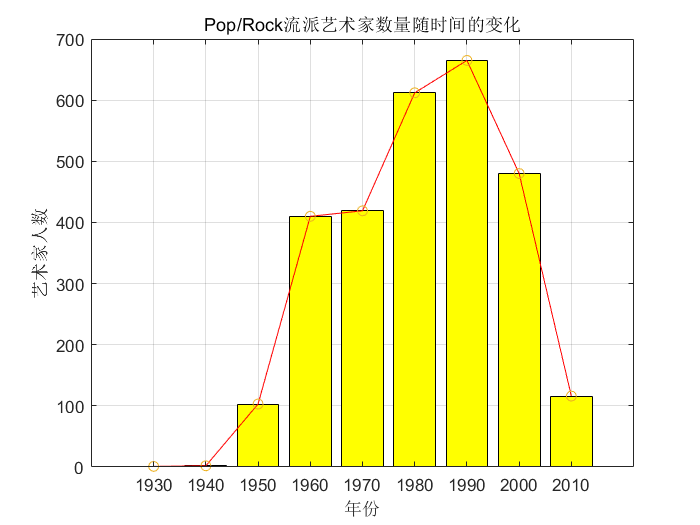


title('Pop/Rock流派艺术家数量随时间的变化')
xlabel('年份')
ylabel('艺术家人数')

绘制Pop/Rock这一流派不同年代的艺术家对其他人的影响

hold off

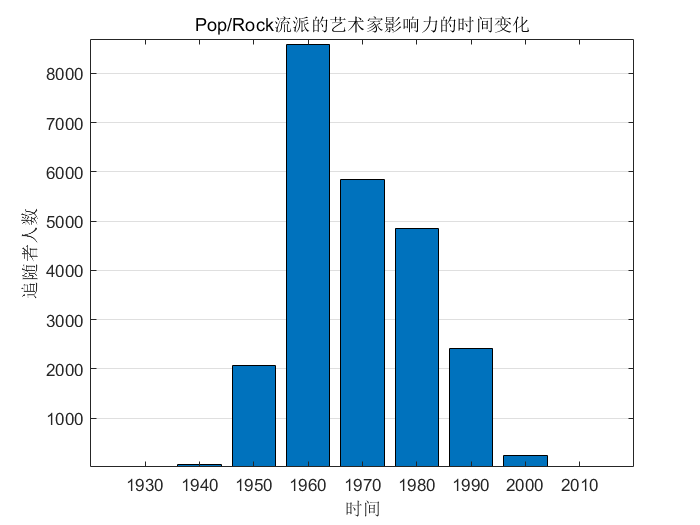

Mat_2 = csvread("2021_ICM_Problem_D_Data\sub_year_degree.csv");
x_arr = 1930:10:2010;
bar(x_arr, Mat_2(:, 2))

xlim([1920 2020])
ylim([10 8700])

xlim([1920.0 2020.0])
ylim([10 8700])
title('Pop/Rock流派的艺术家影响力的时间变化（追随者人数）')
xlabel('时间')
ylabel('追随者人数')

xlim([1920.0 2020.0])
ylim([10 8700])
set(gca,'XGrid','off','YGrid','on')
title('Pop/Rock流派的艺术家影响力的时间变化')

绘制Pop/Rock这以流派不同年代的追随者的变化

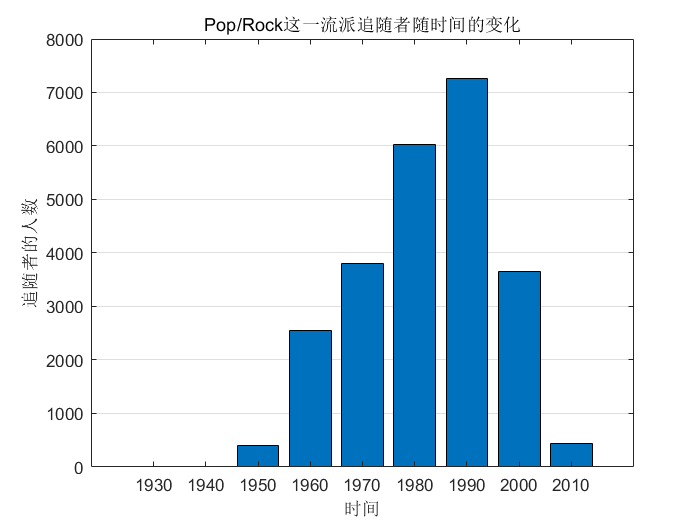

Mat_3 = csvread("2021_ICM_Problem_D_Data\sub_follower_year.csv");
x_arr = 1930:10:2010;
bar(x_arr, Mat_3);

xlim([1918.0 2022.0])
ylim([0 8000])
set(gca,'XGrid','off','YGrid','on')
title('Pop/Rock这一流派追随者随时间的变化')
xlabel('时间')
ylabel('追随者的人数')